# Lab 8 by Cole Bardin Section 62

## Curve Fitting and Global Sea Levels

## Part A

## Question 1

clc, clear, close all
x1 = -2; y1 = 2;   % point #1
x2 = +3; y2 = 7;   % point #2
% Observation vector y
y = [y1;y2];
% Design matrix D
D = [1, x1; 1, x2];
% Parameter vector b
b1 = inv(D)*y

b1 =      4
     1



% Question 2
hold on
xp = -5:0.1:5;
yp = b1(2)*xp + b1(1);
plot(xp, yp, 'b', "LineWidth", 3);
plot(x1, y1, 'o', "MarkerEdgeColor",'b', "MarkerFaceColor",'y', "MarkerSize",12);
plot(x2, y2, 'o', "MarkerEdgeColor",'b', "MarkerFaceColor",'y', "MarkerSize",12);
axis([-5, 5, 0, 10])
title("The Line Through Two Points")
ylabel("y-axis")
xlabel("x-axis")
text(0,6, "y = 4 + 1x", "Color",'r')
text(0,5.5, "\Downarrow", "Color",'r', "FontSize",15)

% Question 3
D2 = transpose(D) * D;
b3 = inv(D2)*D'*y

b3 =     4.0000
    1.0000



% Question 4
x3 = 0; y3 = 4;
y = [y1;y2;y3];
D = [1, x1; 1, x2; 1, x3];
AM = [D, y];
RAM = rref(AM)

RAM =      1     0     4
     0     1     1
     0     0     0


b4 = [RAM(1, 3); RAM(2, 3)]

b4 =      4
     1


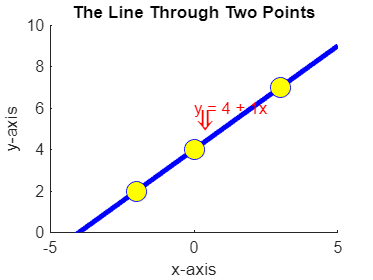

plot(x3, y3, 'o', "MarkerEdgeColor",'b', "MarkerFaceColor",'y', "MarkerSize",12);


% Check that leas-squares method still works
D2 = transpose(D);
b4 = inv(D2*D)*D2*y

b4 =     4.0000
    1.0000



% Question 5
x3 = 0; y3 = 6;
yest = [y1;y2;y3];
D = [1, x1; 1, x2; 1, x3];
AM = [D, y];
RAM5 = rref(AM)

RAM5 =      1     0     4
     0     1     1
     0     0     0



% Question 6
D2 = transpose(D);
b5 = inv(D2*D)*D2*y

b5 =     4.0000
    1.0000



N = length(D);
err = y - yest;
RMSE6 = (err'*err/N)^0.5

RMSE6 = 1.1547


% Question 7
x3 = 0; y3 = 6;

y = [y1;y2;y3];
D = [1, x1, x1^2; 1, x2, x2^2; 1, x3, x3^2];
b7 = inv(D'*D)*D'*y

b7 =     6.0000
    1.3333
   -0.3333


## Part B

## Question 8

clc, clear, close all
load("sea_level_data_May2021.mat")

time = sea_level_data(:,3); % Date/time in years.
gmsl11 = sea_level_data(:,11); % Global mean sea level with seasonal signals
gmsl12 = sea_level_data(:,12); % Global mean sea level - seasonal signals removed

first = [time(1), gmsl11(1), gmsl12(1)]

first = 1.0e+03 *

    1.9930   -0.0370   -0.0376


N = numel(time)

N = 988

last = [time(N), gmsl11(N), gmsl12(N)]

last = 1.0e+03 *

    2.0198    0.0624    0.0571



hold on
grid on
plot(time, gmsl11, 'cyan', "LineWidth",2)
plot(time, gmsl12, 'blue', "LineWidth",2)
plot(time, gmsl11- gmsl12, 'magenta', "LineWidth",2)
title("Global Mean Sea Level Radar Altimetry Data")
xlabel("Year")
ylabel("GMSL")
axis([1990, 2025, -40, 80])
%legend(["With Seasonal Signal", "Seasonal Signal Removed", "Seasonal Signal"], "Location","north")

% Question 9
one = ones(N,1);
%D = [one, time];
t0 = sum(time)/numel(time)

t0 = 2.0064e+03

D = [ones(size(time)), time - t0];
y = gmsl12;

b = inv(D'*D)*D'*y;
yest = D*b;
err = y - yest;
RMSE9 = (err'*err/N)^0.5

RMSE9 = 4.0010

plot(time, yest, 'r', "LineWidth",3)
%legend(["With Seasonal Signal", "Seasonal Signal Removed", "Seasonal Signal", "Best Linear Fit"], "Location","north")

gmsl = @(year) b(1) + b(2) * (year-t0) % anonymous function for best-fit line

gmsl = function_handle with value:
    @(year)b(1)+b(2)*(year-t0)



% Question 10
% Enter the new design matrix D.
D = [ones(size(time)) time-t0 (time-t0).^2];
b = inv(D'*D) * D' *y; % the same, but will have three components!
y_est = D*b; % the same!

% Define an anonymous function for the best-fit quadratic.
% Use capital letters for the quadratic fit.
GMSL = @(year) b(1) + b(2) * (year-t0) + b(3) * (year-t0).^2 % best-fit quadratic

GMSL = function_handle with value:
    @(year)b(1)+b(2)*(year-t0)+b(3)*(year-t0).^2


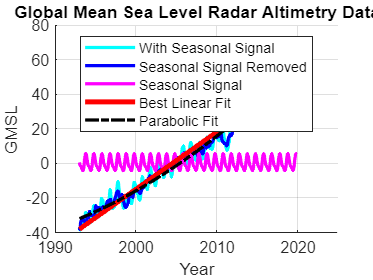


plot(time, GMSL(time), 'k-.', "LineWidth",2)
legend(["With Seasonal Signal", "Seasonal Signal Removed", "Seasonal Signal", "Best Linear Fit", "Parabolic Fit"], "Location","north")